syms t Vpk T s
Vpk=1

Vpk = 1

assume(T,'real')
T=2

T = 2

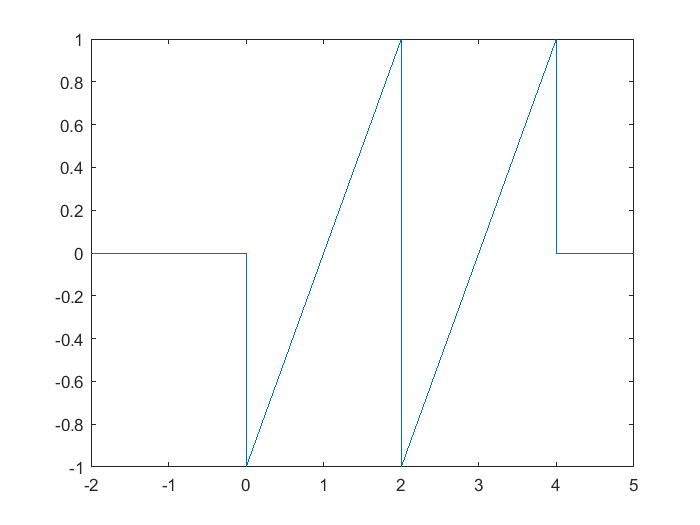

fplot(Vpk*(2*t/T-1)*heaviside(t)-Vpk*(2*(t-T)/T+1)*heaviside(t-T)+Vpk*((2/T*(t-T)-1)*heaviside(t-T)-(2/T*(t-2*T)+2*T/T-1)*heaviside(t-2*T)),[-2 5])


f1=Vpk*((2/T*t-1)*heaviside(t)-(2/T*(t-T)+1)*heaviside(t-T))

$$f1 = \mathrm{heaviside}\left(t\right)\,\left(t-1\right)-\mathrm{heaviside}\left(t-2\right)\,\left(t-1\right)$$

g=laplace(f)

$$g = \mathrm{laplace}\left(\left\{ \begin{array}{cl} \left\lfloor -1\right\rfloor -\mathrm{heaviside}\left(t-2\right)-\frac{3\,t\,\left\lfloor -1\right\rfloor }{2}-\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\frac{t\,{\left\lfloor -1\right\rfloor }^{2}}{2} & \text{ if }t\neq 0\wedge t\neq 2 \end{array}\right.,t,s\right)$$

ft=ilaplace(g)

$$ft = \left\{ \begin{array}{cl} \left\lfloor -1\right\rfloor -\mathrm{heaviside}\left(t-2\right)-\frac{3\,t\,\left\lfloor -1\right\rfloor }{2}-\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\frac{t\,{\left\lfloor -1\right\rfloor }^{2}}{2} & \text{ if }t\neq 0\wedge t\neq 2 \end{array}\right.$$

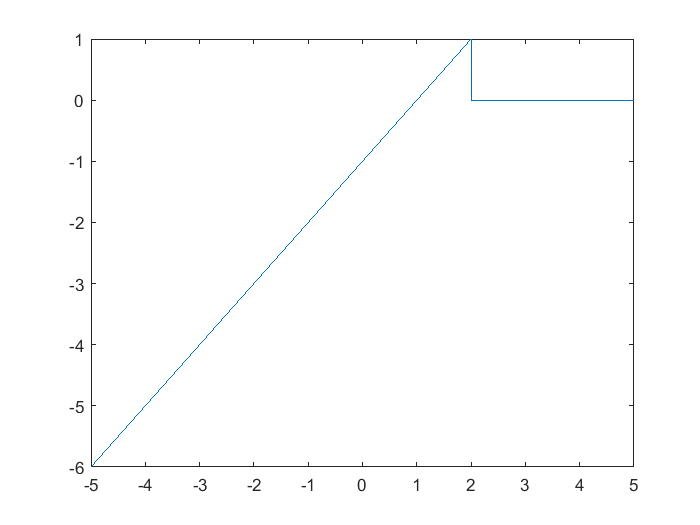

fplot(ft)

%FS=Vpk*(2/(T*s^2)*(1-exp(-T*s))-1/s*(1+exp(-T*s)))
FS=Vpk*(2/T*(1/s^2)-1/s-2/T*exp(-T*s)/s^2-exp(-T*s)/s)/(1-exp(-s*t))

$$FS = \frac{\frac{{\mathrm{e}}^{-2\,s}}{s}+\frac{{\mathrm{e}}^{-2\,s}}{s^{2}}+\frac{1}{s}-\frac{1}{s^{2}}}{{\mathrm{e}}^{-s\,t}-1}$$

f(t)=ilaplace(FS)

$$f(t) = \left\{ \begin{array}{cl} \left\lfloor -1\right\rfloor -\mathrm{heaviside}\left(t-2\right)-\frac{3\,t\,\left\lfloor -1\right\rfloor }{2}-\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\frac{t\,{\left\lfloor -1\right\rfloor }^{2}}{2} & \text{ if }t\neq 0\wedge t\neq 2 \end{array}\right.$$

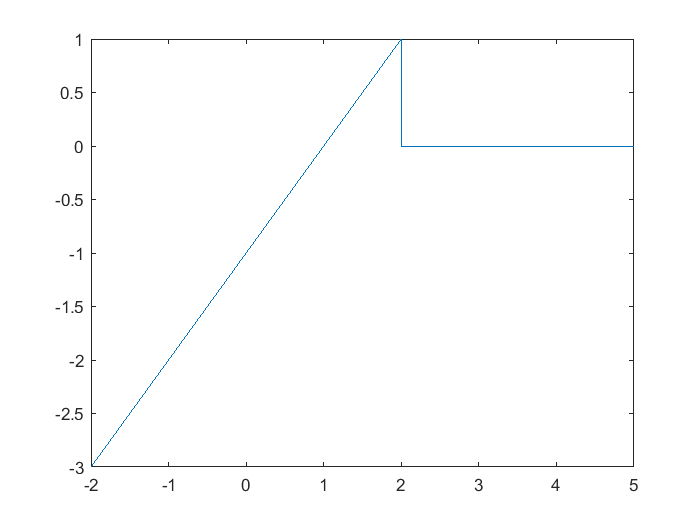

fplot(ilaplace(FS),[-2 5])

laplace((t-T)*heaviside(t-T))

$$ans = \frac{{\mathrm{e}}^{-2\,s}}{s^{2}}$$

ilaplace(1/s^2)

$$ans = t$$

ilaplace(1/s)

$$ans = 1$$

ilaplace(exp(-T*s)/s)

$$ans = \mathrm{heaviside}\left(t-2\right)$$

ilaplace(exp(-T*s)/s^2)

$$ans = \mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)$$

g=laplace(t*heaviside(t))

$$g = \frac{1}{s^{2}}$$


ilaplace(g)

$$ans = t$$

ilaplace(1/s)

$$ans = 1$$